Laboratorio 03

close
clear all

## Generar tiempo

t=1:100

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Generar variable Error

error1 = randn(1,100); %variable
error2=1 +2*randn(1,100); %1 le va sumar a todos los valores 1 y una dv de 2

### Generar plot

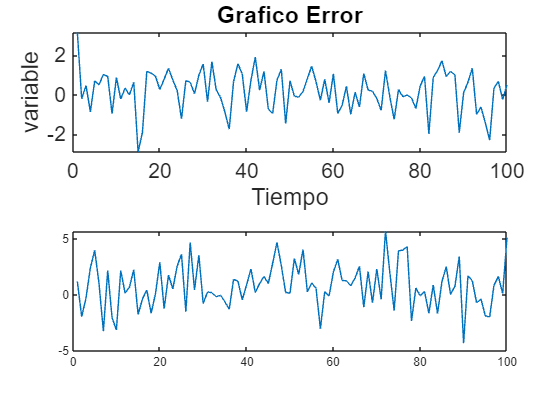

figure %ejecute una ventana nueva para hacer un gráfico
subplot(2,1,1)
plot(t,error1)
title('Grafico Error')
xlabel('Tiempo')
ylabel('variable')
set(gca,'fontsize',16)%gca crea el ultimo objeto que llamo matlab/llama a las propiedades del gráfico
%figure %para no sobreponer la figura sobre otra, sino creo otra ventana con la nueva figura
%h=plot(t, error1,'r')

%mean(error1)
subplot(2,1,2)
plot(t,error2)

Generar tendencia

tend=0.2*t

tend =     0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000   10.0000


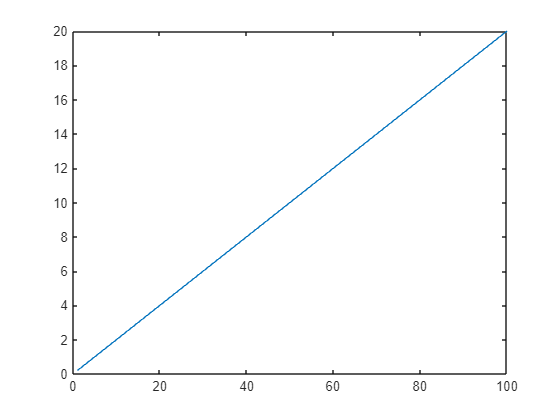

figure
plot(t,tend)

Graficar ST con error + tendencia

ST=tend + error1

ST =     3.3893    0.2051    1.0732   -0.0676    1.7099    1.7132    2.4388    2.5385    0.8491    2.8856    1.9900    2.7472    2.5986    3.4416    0.1038    1.3013    4.5905    4.7041    4.7492    4.2737    4.9965    5.7493    5.3570    5.0147    3.7924    5.9238    6.0374    5.6623    6.7973    7.5681    5.8495    8.0828    6.8543    6.6670    6.1258    5.4669    8.0809    9.1799    8.8540    7.1458    8.9413   10.3147    8.8361   10.0004    8.2900    8.2619   10.1433   10.8973    8.3449   10.7140


Graficar

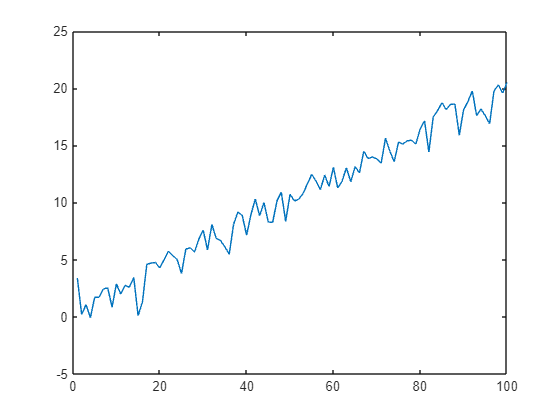

figure
plot(t,ST)% la dv es minima porque las tendencia y el error son de diferentes orden de magnitud. Tendencia de magnitud 10*2

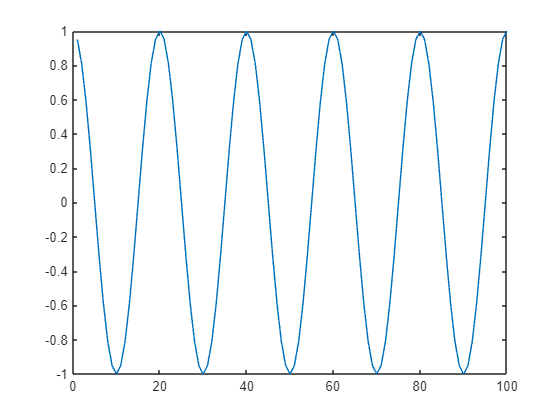

%Ciclos
A1=1; %Amplitud
F1=5/100;
F2=10/100;
F3=20/100;
ciclo1=A1*cos(2*pi*F1*t); %matlab trabaja en radianes
ciclo2=A1*cos(2*pi*F2*t);
ciclo3=A1*cos(2*pi*F3*t);
figure
plot(t,ciclo1)

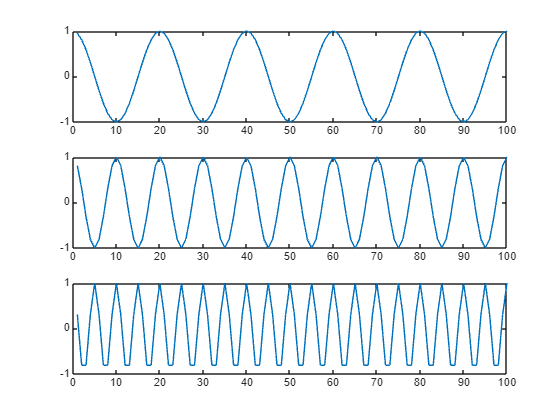

figure
subplot(3,1,1)
plot(t,ciclo1)

subplot(3,1,2)
plot(t,ciclo2)

subplot(3,1,3)
plot(t,ciclo3)

ST= Tendencia + CICLO +error

ST2=tend +ciclo1+ciclo2+error1

ST2 =     5.1493    1.3232    1.3519   -0.5676    0.7099    0.5952    1.5420    2.0385    0.7070    2.8856    1.8479    2.2472    1.7018    2.3236   -0.8962    0.8013    4.8693    5.8222    6.5093    6.2737    6.7566    6.8673    5.6358    4.5147    2.7924    4.8057    5.1406    5.1623    6.6552    7.5681    5.7075    7.5828    5.9575    5.5489    5.1258    4.9669    8.3597   10.2980   10.6141    9.1458   10.7014   11.4327    9.1148    9.5004    7.2900    7.1439    9.2465   10.3973    8.2029   10.7140


ST1=tend +ciclo1+error1

ST1 =     4.3403    1.0142    1.6610    0.2414    1.7099    1.4042    1.8510    1.7295   -0.1020    1.8856    1.0389    1.9382    2.0109    3.1326    0.1038    1.6103    5.1783    5.5131    5.7003    5.2737    5.9476    6.5583    5.9448    5.3238    3.7924    5.6147    5.4496    4.8532    5.8462    6.5681    4.8985    7.2738    6.2665    6.3579    6.1258    5.7759    8.6687    9.9889    9.8051    8.1458    9.8924   11.1237    9.4239   10.3094    8.2900    7.9529    9.5555   10.0883    7.3939    9.7140


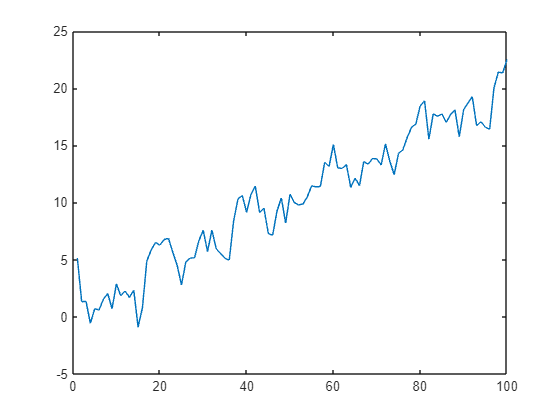


figure
plot(t,ST2)